% SET OPTIONS
importLogs = true;
rtRounding = 10;

%File directories
imgFolder = fullfile('.', '/QuadSimEnv/Results/Traj-0023');
%imgFolder = fullfile('.', '/Sandbox/CamImgs/');
logFile = fullfile('.','/QuadSimEnv/Results/Traj-0023/simout_ideal_100hz.mat');


% INITIALISE CONSTANTS

global g;
g = [0; 0; -9.7952];

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [605.8071 0 316.6903; 0 608.4646 256.6409; 0 0 1.0000]; %31 mm calib
K = [1107 0 960; 0 1107 540; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners/1000; %in m
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
R_uw2rw = map.worldObjectStruct.transforms.rotm_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;


%other variables
p3pResult = struct();
inlierThreshold = 0.5;


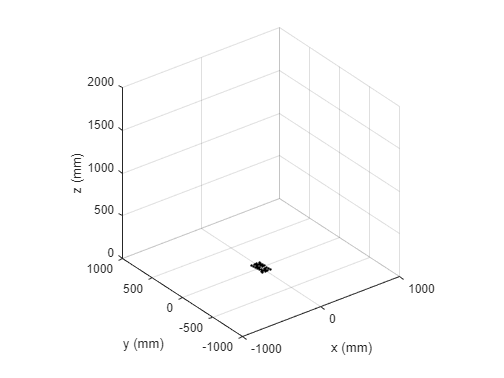

%INTIALISE PLOT
close all

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Verification', 'EKF');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);

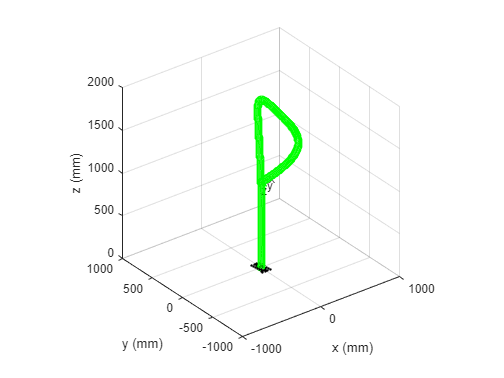

%IMPORT & PLOT LOGGED DATA
if importLogs ==true
    [quad_rtHist_GT, quad_timeHist_GT, quad_stateHist_GT, cam_timeHist_GT, imuHist] = imgFuncs.importSimLog(logFile,  R_uw2rw);
    lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, quad_rtHist_GT);
end

%IMPORT IMAGES
[I_seq, I_seq_times] = imgFuncs.importImageSeq(imgFolder);

Working on frame 1


Discarding frame 1


Working on frame 2


Discarding frame 2


Working on frame 3


Discarding frame 3


Working on frame 4


Discarding frame 4


Working on frame 5


Discarding frame 5


Working on frame 6


Discarding frame 6


Working on frame 7


Discarding frame 7


Working on frame 8


Discarding frame 8


Working on frame 9


Discarding frame 9


Working on frame 10


Discarding frame 10


Working on frame 11


Discarding frame 11


Working on frame 12


Discarding frame 12


Working on frame 13


Discarding frame 13


Working on frame 14


Discarding frame 14


Working on frame 15


Discarding frame 15


Working on frame 16


Discarding frame 16


Working on frame 17


Discarding frame 17


Working on frame 18


Discarding frame 18


Working on frame 19


Discarding frame 19


Working on frame 20


Discarding frame 20


Working on frame 21


Discarding frame 21


Working on frame 22
Working on frame 23
Working on frame 24
Working on frame 25
Working on frame 26
Working on frame 27
Working on frame 28
Working on frame 29
Working on frame 30
Working on frame 31
Working on frame 32
Working on frame 33
Working on frame 34
Working on frame 35
Working on frame 36
Working on frame 37
Working on frame 38
Working on frame 39
Working on frame 40
Working on frame 41
Working on frame 42


Discarding frame 42


Working on frame 43
Working on frame 44
Working on frame 45
Working on frame 46
Working on frame 47
Working on frame 48
Working on frame 49
Working on frame 50
Working on frame 51
Working on frame 52
Working on frame 53
Working on frame 54
Working on frame 55
Working on frame 56
Working on frame 57
Working on frame 58
Working on frame 59
Working on frame 60
Working on frame 61
Working on frame 62
Working on frame 63


Discarding frame 63


Working on frame 64
Working on frame 65
Working on frame 66
Working on frame 67
Working on frame 68
Working on frame 69


Discarding frame 69


Working on frame 70
Working on frame 71
Working on frame 72
Working on frame 73


Discarding frame 73


Working on frame 74
Working on frame 75


Discarding frame 75


Working on frame 76
Working on frame 77
Working on frame 78
Working on frame 79
Working on frame 80
Working on frame 81
Working on frame 82
Working on frame 83
Working on frame 84
Working on frame 85
Working on frame 86
Working on frame 87
Working on frame 88
Working on frame 89
Working on frame 90
Working on frame 91


Discarding frame 91


Working on frame 92
Working on frame 93
Working on frame 94
Working on frame 95
Working on frame 96
Working on frame 97
Working on frame 98


Discarding frame 98


Working on frame 99
Working on frame 100
Working on frame 101
Working on frame 102
Working on frame 103
Working on frame 104
Working on frame 105
Working on frame 106
Working on frame 107


Discarding frame 107


Working on frame 108
Working on frame 109
Working on frame 110
Working on frame 111
Working on frame 112
Working on frame 113
Working on frame 114
Working on frame 115
Working on frame 116
Working on frame 117
Working on frame 118
Working on frame 119
Working on frame 120
Working on frame 121
Working on frame 122
Working on frame 123
Working on frame 124
Working on frame 125
Working on frame 126
Working on frame 127
Working on frame 128
Working on frame 129
Working on frame 130
Working on frame 131
Working on frame 132
Working on frame 133
Working on frame 134
Working on frame 135
Working on frame 136
Working on frame 137
Working on frame 138
Working on frame 139
Working on frame 140
Working on frame 141
Working on frame 142
Working on frame 143
Working on frame 144
Working on frame 145


Discarding frame 145


Working on frame 146
Working on frame 147
Working on frame 148
Working on frame 149
Working on frame 150


Discarding frame 150


Working on frame 151
Working on frame 152
Working on frame 153
Working on frame 154
Working on frame 155
Working on frame 156
Working on frame 157
Working on frame 158
Working on frame 159
Working on frame 160
Working on frame 161


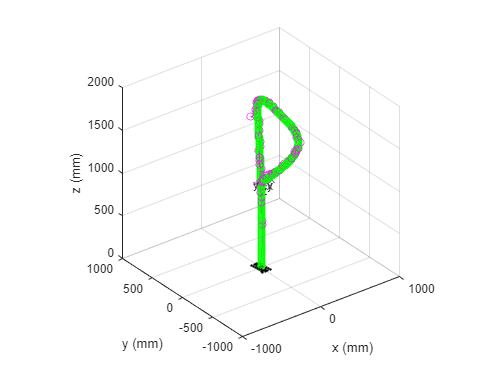

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
goodFrameCounter = 0;
for i=1:size(I_seq,3)

    disp(strcat("Working on frame ", string(i)));
    
    %Get current frame
    I=I_seq(:,:,i);
    imageArrSize = size(I);
    imageSize=imageArrSize(1:2);

    %Find checkerboard corners
    [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
    x_pnts_i = transpose(x_pnts_i);    

    %discard any frames where too few corners have been detected
    if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
        disp(strcat("Discarding frame ", string(i)));
        continue
    end
    %Otherwise, continue:
    goodFrameCounter = goodFrameCounter +1;
    %Extract useful information
    time_I = I_seq_times(:,i); %time associated with frame
    [~,closestIndex] = min(abs(cam_timeHist_GT-time_I));
    if goodFrameCounter == 1
        startIndex =closestIndex;
    end
    Rt_log_i = quad_rtHist_GT(:,:,closestIndex);


    %Run P3P
    p3pResult = runP3P(p3pResult, time_I, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, inlierThreshold, rtRounding,  'KneipN');
    plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);


    %Calculate error
    if importLogs == true
        p3pResult = calcRtError(p3pResult, quad_rtHist_GT, quad_timeHist_GT);    
    end

    % %Display checkerboard image for this iteration - for troubleshooting
    % if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
    %     if i==1
    %         checkerFig = figure();
    %         checkerAx = axes('Parent', checkerFig);
    %         checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
    %     else
    %         checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
    %         drawnow;
    %     end 
    % end

 end

 
 p3pResultFile = fullfile('.', '/Results/p3pResult.mat')

p3pResultFile = '.\Results\p3pResult.mat'

 save(p3pResultFile,  'p3pResult'); 
 


## run 3D state estimator

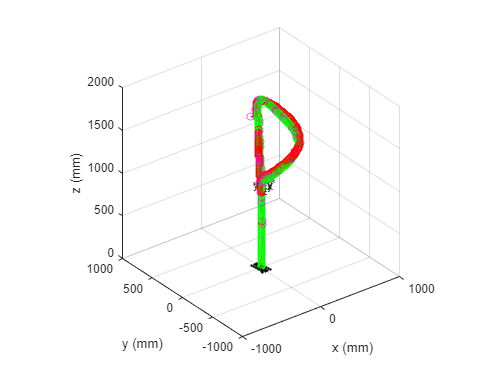

%Clear persistent variables
clear persistent

g = [0; 0; -9.81];

%import sim log (again)
[quad_rtHist_GT, quad_timeHist_GT, quad_stateHist_GT, cam_timeHist_GT, imuHist] = imgFuncs.importSimLog(logFile,  R_uw2rw);
%temp:
simData = load(logFile);
for i=1:size(simData.out.qdot_rq2rw.signals.values, 3)
    qdotHist(:, i) = simData.out.qdot_rq2rw.signals.values(:, 1, i);
end


%set offsets
%Known coordinate transformations (mapping)
R_uw2rw = map.worldObjectStruct.transforms.rotm_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;
Rt_rc2rq = map.worldObjectStruct.transforms.rt_gencam2genquad;


%Import data
p3pResultFile = fullfile('.','/Results/p3pResult.mat');
p3pResultLoad = load(p3pResultFile);
p3pData = p3pResultLoad.p3pResult.KneipN;
p3pTimes = p3pData.time;

%% IMPORT HISTORIES

%Get ground truth state history for comparison
x_hist_GT = quad_stateHist_GT(:,:);

%Get control input history
%u_hist = [imuHist(:,:); qdotHist]; %includes measurement times in row 1
u_hist = imuHist;

%Get measurement history
pos = p3pData.Rt(1:3, 4, :); %in m
rot = p3pData.Rt(1:3, 1:3, :);
pos = reshape(pos, 3, size(pos, 3));
ori_euler = zeros(3, size(rot, 3));
ori_quat = zeros(4, size(rot, 3));
for i=1:size(rot,3)
    eul = rotm2eul(rot(:,:,i), 'XYZ');
    ori_euler(:,i) = transpose(eul);
    ori_quat(:,i) = transpose(rotm2quat(rot(:,:,i)));
end
z_hist = [p3pTimes; pos; ori_quat];

%% INITIALISE STATE AND ESTIMATOR VARIABLES
start = 2; %Which log values to start at
%Why using second value? There's something wrong with the first. probably due to derivatives in model)

%**** 10 elements ************
% %Initialise state - 10 el
%  x_k = [x_hist_GT(1:10,start)];
% 
% %State covariance
% P_k = diag([0.001, 0.001, 0.001, 0.001, 0.001,  0.001, 0.001, 0.001, 0.001, 0.001]); %Initial, 10 el
% 
% %process noise covariance (noise space)
% Q = diag([0.01, 0.01, 0.01, 0.1, 0.1, 0.1]); %10 el - [w_g, w_acc]
% 
% %and measurement covariance
% W =diag([0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1]); %10 el 

%***************************


%**** 16 elements *****

%Initialise state - 16 el
%ba_calib = [0;-0;-0];
%bg_calib = [0.0; 0.0; 0.0];
%x_k = [x_hist_GT(:,start); ba_calib; bg_calib];
x_k = [x_hist_GT(:,start)];

%State covariance
P_k = diag([0.001, 0.001, 0.001, ...
            0.001, 0.001, 0.001, 0.001, ...
            0.001, 0.001, 0.001, ...
            0.2, 0.2, 0.2, ...
            0.01, 0.01, 0.01]); %Initial, 16 el

%process noise covariance (noise space)
Q = diag([0.01, 0.01, 0.01, 0.1, 0.1, 0.1, 0.01, 0.01, 0.01, 0.001, 0.001, 0.001]); %16 el - [w_g, w_acc, w_ba, w_ba]

%and measurement covariance
W =diag([0.1, 0.1, 0.1, 0.01, 0.01, 0.01, 0.01]);  

%***************************

%At each time step
%Which time steps?
t_delta = u_hist(1,2) - u_hist(1,1);

%initialise EKF output history (do it after first state to get sizes right)
stateHist_EKF = zeros(size(x_k, 1)+1, size(u_hist,2));
stateCovHist_EKF = zeros(size(x_k, 1), size(x_k, 1), size(u_hist,2));
rtHist_ekf = zeros(3, 4, size(u_hist,2));
stateHist_EKF(2:end,1) =x_k;
processTermHist_EKF = zeros(size(stateHist_EKF));
zHatHist_EKF = zeros(8, size(stateHist_EKF, 2));
xHatHist_EKF = zeros(size(stateHist_EKF));

count = 1;
for i=start:(size(u_hist,2)-1)
   
    t_k = u_hist(1,i); %current time
    u_k = u_hist(2:end, i); %current control input - INCLUDE SCALE FACTOR HERE?
    % if i > 1
    %     x_k = x_hist_GT(:, i);
    % end
    
    %check if there is a measurement for this time
    [closestDiff, closestIndex] = min(abs(z_hist(1,:)-t_k));
    if (((closestDiff) <= (t_delta)) && (z_hist(1, closestIndex) <= t_k))
        z_k = z_hist(2:end, closestIndex);
    else
        z_k = NaN; %no new measurement
    end
    %z_k = NaN;
    

    %run EKF to find next state
    [x_k, P_k, proTerm_k, xHat_k, zHat_k, z_k] = EKF_3dQuad_16el_funcs.EKF_loop(g, x_k, P_k, u_k, Q, z_k, W, t_delta, Rt_imu2rq, Rt_rc2rq, count);
    stateHist_EKF(:,i+1) = [(t_k+t_delta); x_k];
    stateCovHist_EKF(:,:,i+1) = [P_k];
    processTermHist_EKF(:,i) = [(t_k); proTerm_k];
    xHatHist_EKF(:,i) = [(t_k+t_delta); xHat_k];
    zHatHist_EKF(:,i) = [(t_k); zHat_k];

    %RECREATE RT matrix for plotting
    rtHist_ekf(:,4,i+1)= [(x_k(1:3,1))];
    rtHist_ekf(:,1:3,i+1)= (quat2rotm(transpose(x_k(4:7, 1))));

    % Correct z_hist (enforce quaternion "continuity")
    if ~isnan(z_k)
       z_hist(2:end, closestIndex) = z_k;
    end
    
    count = count + 1;
end

%Clear persistent variables
clear EKF_3dQuad_16el_funcs.EKF_loop.dyn_update


plotStruct.traj.plotLines.EKF.Data = rtHist_ekf;
p3pPlotting.updateTraj(plotStruct.traj.plotLines.EKF.line, plotStruct.traj.plotLines.EKF.frameText, plotStruct.traj.plotLines.EKF.frameLines, rtHist_ekf)

drawnow

## Calculate errors

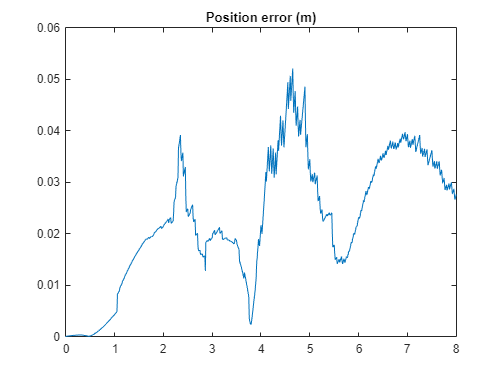

errArr = zeros(3, size(stateHist_EKF,2));

for i=1:size(stateHist_EKF, 2)

    %Extract timestamp
    t = stateHist_EKF(1, i);

    %Find the closest ground truth measurement for this time
    [closestDiff, closestIndex] = min(abs(quad_timeHist_GT(1,:)-t));
    state_GT = quad_stateHist_GT(:, closestIndex);

    errArr(1, i) = t;
    [errArr(2, i), errArr(3, i)] = getPoseError(state_GT, stateHist_EKF(2:end, i));

end

%%Plot them

errPlot_pos = figure();
errAx_pos = axes('Parent', errPlot_pos);
plot(errAx_pos, errArr(1,:), errArr(2,:));
title('Position error (m)');

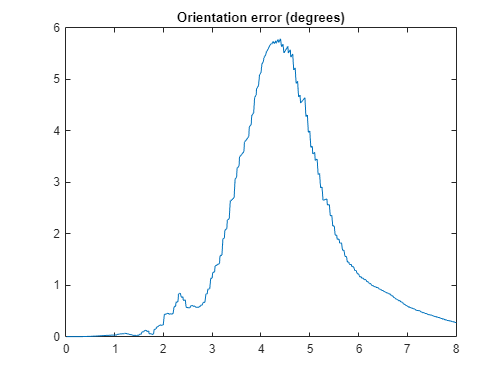


errPlot_ang = figure();
errAx_ang = axes('Parent', errPlot_ang);
plot(errAx_ang, errArr(1,:), errArr(3,:));
title('Orientation error (degrees)');

## Plot state development

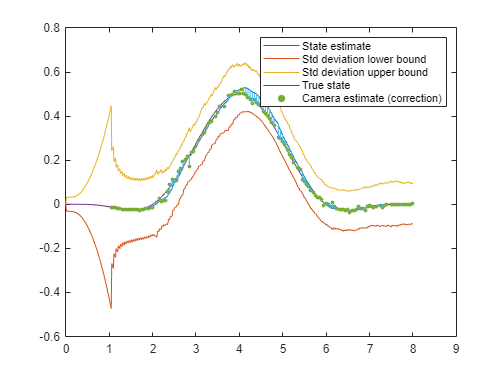

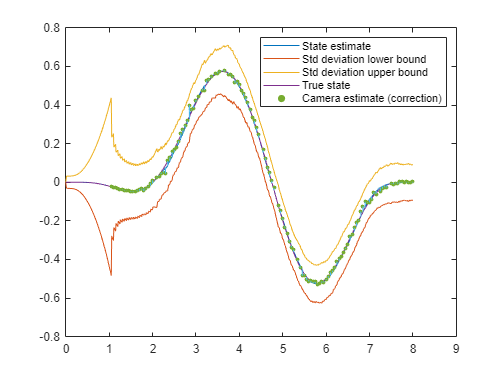

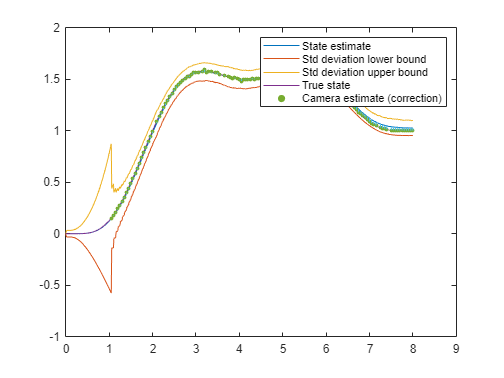

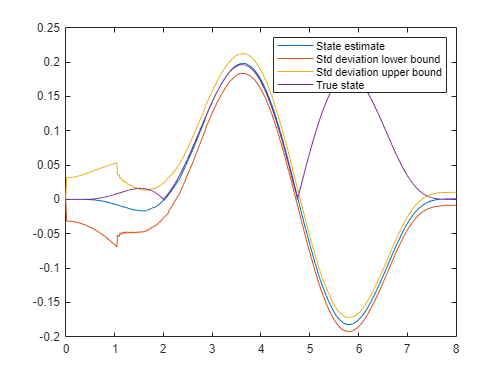

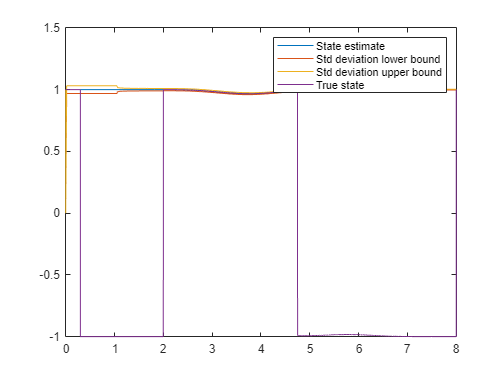

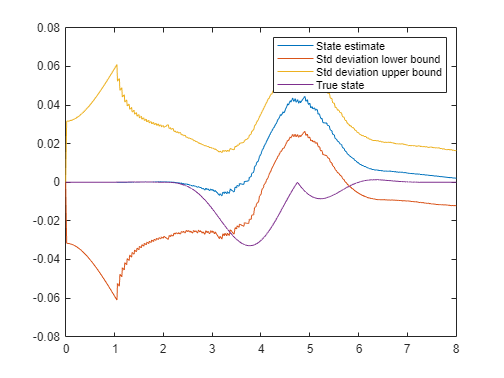

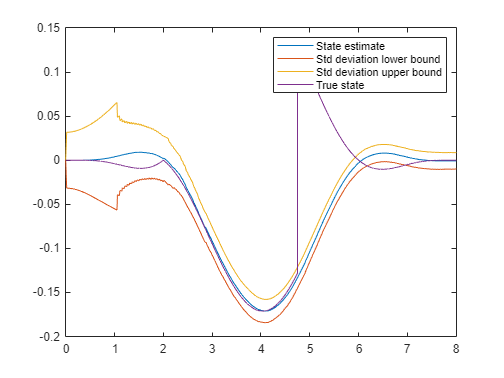

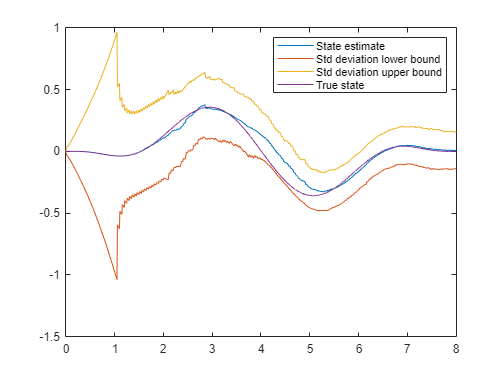

%%Convert quaternions to euler angles --> more meaningful

%EKF estimates
orientCov_eul = zeros(3,3,size(stateHist_EKF, 2));
orient_EKF_eul = zeros(3,size(stateHist_EKF, 2));
for t=start:size(stateHist_EKF, 2)

    %convert quaternion estimate to euler
    orient_EKF_eul(:,t) = (quat2eul(stateHist_EKF(4:7, t)', 'XYZ'))'; %convert quaternion to euler
    q = stateHist_EKF(4:7, t);

    %propagate covariance
    orientCov_quat = stateCovHist_EKF(4:7, 4:7, t);
    jacob = jacobianEultoQuat(q);
    orientCov_eul(:,:,t) = jacob * orientCov_quat * jacob';

end

%P3P estimates
orient_P3P_eul = zeros(3,size(z_hist, 2));
for t=start:size(z_hist, 2)
    %convert quaternion estimate to euler
    orient_P3P_eul(:,t) = (quat2eul(z_hist(4:7, t)', 'XYZ'))'; %convert quaternion to euler
end

%Ground truth
orient_gt_eul = zeros(3,size(quad_stateHist_GT, 2));
for t=start:size(quad_stateHist_GT, 2)
    %convert quaternion estimate to euler
    orient_gt_eul(:,t) = (quat2eul(quad_stateHist_GT(4:7, t)', 'XYZ'))'; %convert quaternion to euler
end

%Recreate state histories
%stateHist_EKF_eul = 

%% DO PLOTTING:

%for each state variable
for i=1:size(x_k, 1)
    
    figure(); %create figure
    title(strcat('State variable evolution: ', string(i)));

    %PLOT CHANGING STATE
    x = stateHist_EKF(1,:);
    y = stateHist_EKF((1+i),:);
    plot(x, y);
        
    drawnow;
    hold on;
    
    %PLOT VARIANCE
    %x = stateHist_EKF(1,:);
    %extract variance
    stateVariance = zeros(1, size(stateHist_EKF, 2)); %initialise array
    for t=1:size(stateHist_EKF, 2)
        stateVariance(1,t)=stateCovHist_EKF(i,i,t);
    end
    stateVariance = sqrt(stateVariance);
    lowerCurve = y - abs(stateVariance);
    upperCurve = y + abs(stateVariance);
    plot(x, lowerCurve);
    hold on;
    plot(x, upperCurve);
    hold on;
    % fill(x, [y; upperCurve],[.9 .9 .9],'linestyle','none');
    % hold on;
    % 
    % fill(x, [lowerCurve; y],[.9 .9 .9],'linestyle','none');
    % hold on;
    %line(x,y)
    %errorbar(x, y, -dy, dy);
    % 
    % drawnow;
    % hold on;


    %PLOT GROUND TRUTH
    x = quad_timeHist_GT(1,:);
    y = quad_stateHist_GT((i),:);
    plot(x, y);
    hold on;

    %plot corrections, if any (i.e., measurements in state space)
    if i<=3
        x = z_hist(1,:);
        y = z_hist(1+i,:);
        scatter(x,y,10, "filled");
        hold on;

        %mark estimate that was corrected
        correctedEst = zeros(1, size(z_hist, 2));
        for t=1:size(z_hist, 2)
            t_k =  z_hist(1, t);
            [closestDiff, closestIndex] = min(abs(stateHist_EKF(1,:)-z_hist(1,t)));
            correctedEst(1, t) = stateHist_EKF(1+i, closestIndex);
        end
        y = correctedEst;
        %scatter(x, y, 10, "filled")
        %hold on;
        quiver(x, correctedEst, zeros(1, size(correctedEst, 2)), ((z_hist(1+i,:)-correctedEst)), 0);
       
    end
    



    legend('State estimate', 'Std deviation lower bound', 'Std deviation upper bound', 'True state', 'Camera estimate (correction)')

    hold off;


end


function j = jacobianEultoQuat(q)

j_11 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_12 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_13 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_14 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_21 = 2*q(4) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_22 = 2*q(3) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_23 = 2*q(2) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_24 = 2*q(1) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_31 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_32 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_33 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_34 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );

j = [j_11 j_12 j_13 j_14;
     j_21 j_22 j_23 j_24;
     j_31 j_32 j_33 j_34];
end

